### 1. How does the impedance change with the angle in the E and H plane? Why?

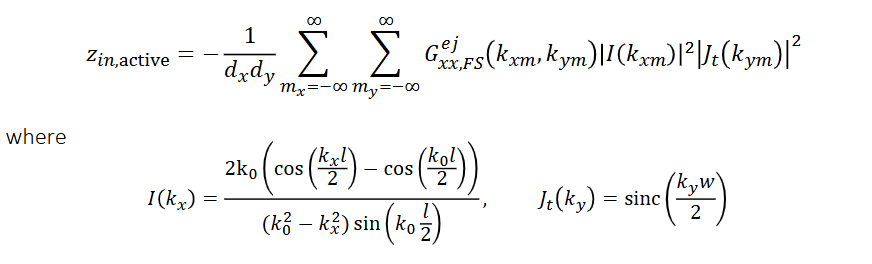

The E D H-plane plot for both cases can be found as follows:

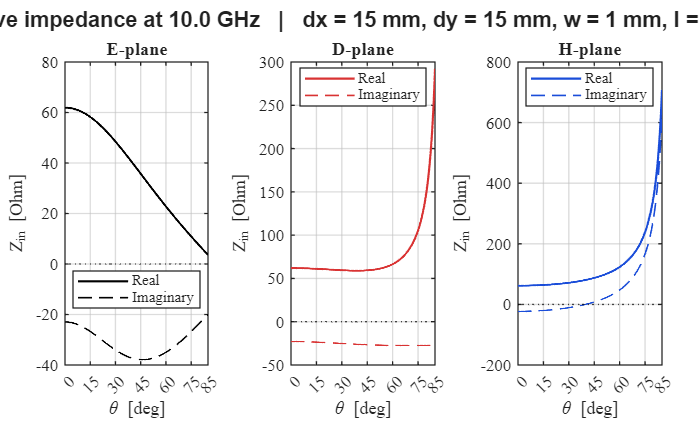


Case: dx = 15 mm, dy = 15 mm, w = 1 mm, l = 14 mm
E-plane: Re{Zin} 61.94 -> 3.59 Ohm, Im{Zin} -22.93 -> -19.94 Ohm for theta 0 -> 85 deg
D-plane: Re{Zin} 61.94 -> 292.22 Ohm, Im{Zin} -22.93 -> -27.21 Ohm for theta 0 -> 85 deg
H-plane: Re{Zin} 61.94 -> 708.05 Ohm, Im{Zin} -22.93 -> 638.95 Ohm for theta 0 -> 85 deg


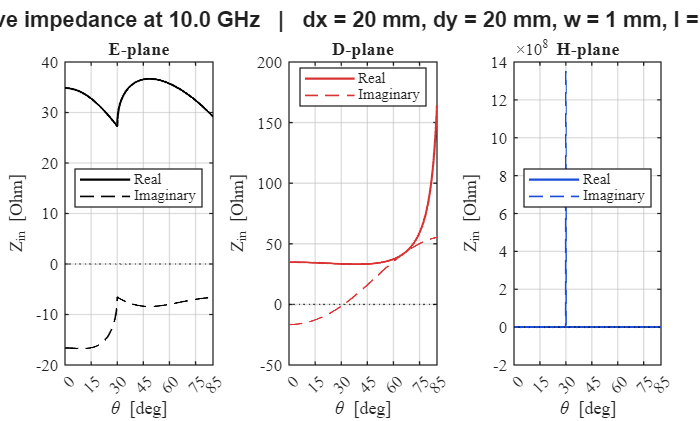


Case: dx = 20 mm, dy = 20 mm, w = 1 mm, l = 14 mm
E-plane: Re{Zin} 34.84 -> 29.19 Ohm, Im{Zin} -16.63 -> -6.61 Ohm for theta 0 -> 85 deg
D-plane: Re{Zin} 34.84 -> 164.37 Ohm, Im{Zin} -16.63 -> 55.32 Ohm for theta 0 -> 85 deg
H-plane: Re{Zin} 34.84 -> 438.57 Ohm, Im{Zin} -16.63 -> -56.52 Ohm for theta 0 -> 85 deg


clc; clear; close all;

% Assumption for the scan planes of an x-directed dipole array:
% E-plane: phi = 0 deg, D-plane: phi = 45 deg, H-plane: phi = 90 deg.

c0 = 3e8;
f0 = 10e9;
k0 = 2 * pi * f0 / c0;

theta_deg = linspace(0, 85, 681);
theta = deg2rad(theta_deg);

plane_names = {'E-plane', 'D-plane', 'H-plane'};
phi_list = [0, pi / 4, pi / 2];
plane_colors = {'k', [0.85 0.2 0.2], [0.1 0.3 0.85]};

cases(1) = struct('dx', 15e-3, 'dy', 15e-3, 'w', 1e-3, 'l', 14e-3);
cases(2) = struct('dx', 20e-3, 'dy', 20e-3, 'w', 1e-3, 'l', 14e-3);

Mx = 100;
My = 100;
mx = -Mx:Mx;
my = -My:My;
[MX, MY] = meshgrid(mx, my);

for idx_case = 1:numel(cases)
    Zin_planes = zeros(numel(phi_list), numel(theta));

    for idx_plane = 1:numel(phi_list)
        phi = phi_list(idx_plane);

        for idx_theta = 1:numel(theta)
            kx_scan = k0 * sin(theta(idx_theta)) * cos(phi);
            ky_scan = k0 * sin(theta(idx_theta)) * sin(phi);

            kxm = kx_scan + 2 * pi * MX / cases(idx_case).dx;
            kym = ky_scan + 2 * pi * MY / cases(idx_case).dy;

            Gxx_fs = freeSpaceGxx(k0, kxm, kym);
            Ix = dipoleSpectrum(kxm, k0, cases(idx_case).l);
            Jt = sinc0(kym * cases(idx_case).w / 2);

            Z_terms = -(1 / (cases(idx_case).dx * cases(idx_case).dy)) .* ...
                Gxx_fs .* abs(Ix).^2 .* abs(Jt).^2;

            Zin_planes(idx_plane, idx_theta) = sum(Z_terms, 'all');
        end
    end

    makeAngleFigure(theta_deg, Zin_planes, plane_names, plane_colors, cases(idx_case), f0);
    reportObservations(theta_deg, Zin_planes, plane_names, cases(idx_case));
end


function Gxx = freeSpaceGxx(k0, kx, ky)
    eta0 = 120 * pi;
    kz = spectralKz(k0, kx, ky);
    Gxx = -(eta0 ./ (2 * k0 .* kz)) .* (k0^2 - kx.^2);
end

function kz = spectralKz(k0, kx, ky)
    kt2 = kx.^2 + ky.^2;
    kz = zeros(size(kt2));

    propagating = kt2 <= k0^2;
    kz(propagating) = sqrt(k0^2 - kt2(propagating));
    kz(~propagating) = -1i * sqrt(kt2(~propagating) - k0^2);
end

function Ix = dipoleSpectrum(kx, k0, l)
    numerator = 2 * k0 .* (cos(kx * l / 2) - cos(k0 * l / 2));
    denominator = (k0^2 - kx.^2) .* sin(k0 * l / 2);

    Ix = numerator ./ denominator;

    singular_mask = abs(abs(kx) - k0) < 1e-10 * max(k0, 1);
    Ix(singular_mask) = l / 2;
end

function y = sinc0(x)
    y = ones(size(x));
    nz = abs(x) > 1e-12;
    y(nz) = sin(x(nz)) ./ x(nz);
end

function makeAngleFigure(theta_deg, Zin_planes, plane_names, plane_colors, params, f0)
    figure('Color', 'w');
    tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

    for idx_plane = 1:numel(plane_names)
        nexttile;
        hold on; box on; grid on;
        plot(theta_deg, real(Zin_planes(idx_plane, :)), '-', ...
            'Color', plane_colors{idx_plane}, 'LineWidth', 1.3);
        plot(theta_deg, imag(Zin_planes(idx_plane, :)), '--', ...
            'Color', plane_colors{idx_plane}, 'LineWidth', 1.0);
        yline(0, 'k:', 'LineWidth', 0.8);
        xlabel('\theta [deg]');
        ylabel('Z_{in} [Ohm]');
        title(plane_names{idx_plane});
        legend('Real', 'Imaginary', 'Location', 'best');
        styleAngleAxes(gca, theta_deg);
    end

    sgtitle(sprintf(['Active impedance at %.1f GHz   |   dx = %.0f mm, dy = %.0f mm, ', ...
        'w = %.0f mm, l = %.0f mm'], ...
        f0 / 1e9, params.dx * 1e3, params.dy * 1e3, params.w * 1e3, params.l * 1e3), ...
        'FontWeight', 'bold');
end

function styleAngleAxes(ax, theta_deg)
    xlim(ax, [theta_deg(1), theta_deg(end)]);
    xticks(ax, [0 15 30 45 60 75 85]);
    ax.FontName = 'Times New Roman';
    ax.FontSize = 10;
    ax.GridColor = [0.75, 0.75, 0.75];
    ax.GridAlpha = 0.55;
    ax.LineWidth = 0.8;
end

function reportObservations(theta_deg, Zin_planes, plane_names, params)
    fprintf('\nCase: dx = %.0f mm, dy = %.0f mm, w = %.0f mm, l = %.0f mm\n', ...
        params.dx * 1e3, params.dy * 1e3, params.w * 1e3, params.l * 1e3);

    for idx_plane = 1:numel(plane_names)
        re_start = real(Zin_planes(idx_plane, 1));
        re_end = real(Zin_planes(idx_plane, end));
        im_start = imag(Zin_planes(idx_plane, 1));
        im_end = imag(Zin_planes(idx_plane, end));

        fprintf('%s: Re{Zin} %.2f -> %.2f Ohm, Im{Zin} %.2f -> %.2f Ohm for theta %.0f -> %.0f deg\n', ...
            plane_names{idx_plane}, re_start, re_end, im_start, im_end, ...
            theta_deg(1), theta_deg(end));
    end
end

At a fixed frequency, the active input impedance depends on the scan angle because scanning changes phase progression between neighboring elements and therefore changes the Floquet spectrum of the periodic array. Since the active impedance is obtained by summing the contribution of all Floquet modes, both the real and imaginary parts vary with angle as the mutual coupling between elements changes.

In the E-plane, the variation is relatively smooth. For an $x$-directed dipole, scanning in the E-plane mainly changes $k_x$. In this case, the dipole current spectrum and the Green's-function term vary in a way that partially smooths the response, so the impedance changes gradually with angle.

In the H-plane, the impedance is much more sensitive to the scan angle. Here the scan mainly changes$k_{y\;}$, while $k_x$ remains approximately fixed, so the same smoothing effect is not present. As the angle increases, higher-order Floquet modes can approach cutoff and eventually become propagating. When this happens, the corresponding contribution to the active impedance becomes very large, producing a sharp increase or even a singular behavior in the impedance. This explains why the H-plane curves show a much stronger angular dependence than the E-plane curves.

Therefore, the main conclusion is that the active impedance changes more mildly in the E-plane and much more strongly in the H-plane, because the H-plane scan more easily excites higher-order Floquet-mode effects and cutoff singularities.

### 2. What type of singularities appear in the active input impedance?

The singularities that appear in the active input impedance are grating-lobe singularities.

These singularities occur when one of the higher-order Floquet harmonics satisfies the condition:


$$k_{xm}^2 +k_{ym}^2 =k_0^2$$


so that its longitudinal wavenumber becomes


$$k_{z,mn} =\sqrt{k_0^2 -k_{xm}^2 -k_{ym}^2 }=0$$


At this point, the Floquet mode is at cutoff, and the spectral Green's function contains a term proportional to $1/k_{z,mn}$. Therefore, the contribution of that mode becomes very large, which produces a singularity in the active input impedance.

For the $d_{x\;} =d_{y\;} =15\;\mathrm{mm}$ case, the singularity appears at $\theta =90\;\;\deg$. And for the $d_{x\;} =d_{y\;} =15\;\textrm{mm}$ case, the singularity appears at $\theta =30\;\deg$. This can be found via the following calculation:

Given: 

$k_{z,mn} =\sqrt{k_0^2 -k_{xm}^2 -k_{yn}^2 }$,     $k_{xm} =k_0 \sin \theta \cos \phi +\frac{2\pi m}{d_x },~~~~k_{yn} =k_0 \sin \theta \sin \phi +\frac{2\pi n}{d_y }.$

A singularity can occur when


$$k_{z,mn} =0\to k_{xm}^2 +k_{yn}^2 =k_0^2 .$$


## H-plane spike

In the H-plane,$\phi =90^{\circ }$, so


$$k_x^{\textrm{scan}} =0,~~~~k_y^{\textrm{scan}} =k_0 \sin \theta .$$


Therefore,


$$k_{xm} =\frac{2\pi m}{d_x },~~~~k_{yn} =k_0 \sin \theta +\frac{2\pi n}{d_y }.$$


The first strong spike comes from the $m=0,~~n=-1$ mode, then


$$k_{x,0} =0,~~~~k_{y,-1} =k_0 \sin \theta -\frac{2\pi }{d_y }.$$


Applying the singularity condition gives


$${\left(k_0 \sin \theta -\frac{2\pi }{d_y }\right)}^2 =k_0^2 \;\;\to \;$$

$${\left(\sin \theta -\frac{\lambda }{d_y }\right)}^2 =1.$$


So


$$\sin \theta -\frac{\lambda }{d_y }=\pm 1$$


and therefore


$$\sin \theta =\frac{\lambda }{d_y }\pm 1.$$


## Case $d_{x\;} =d_{y\;} =20\;\mathrm{mm}$

$\lambda =\frac{c}{f}=\frac{3\times 10^8 }{10^{10} }=0.03\;\textrm{m}=30\;\textrm{mm}.\;\;\;\to \;\;$$\frac{\lambda }{d_y }=\frac{30}{20}=1.5.$  So   $\sin \theta =1.5\pm 1.$

This gives

$\sin \theta =2.5~~\textrm{(not}\;\textrm{physical)}$ or $\sin \theta =0.5.$

Hence the spike appears at 


$$\theta =\sin^{-1} (0.5)=30^{\circ } .$$


which matches the plot.

## Case$\;d_{x\;} =d_{y\;} =20\;\mathrm{mm}$

Now $\frac{\lambda }{d_y }=\frac{30}{15}=2.$ Then  $\sin \theta =2\pm 1.$ So the only physical solution is $\sin \theta =1~~\Rightarrow ~~\theta =90^{\circ } .$

Therefore, for the $\;d_{x\;} =d_{y\;} =20\;\mathrm{mm}$ spacing, the singularity moves to grazing angle: $\theta =90^{\circ }$

which is why the curve only rises strongly near the end of the scan.

### 3. For scanning in each plane, sketch the grating lobe diagram to explain which modes enter the visible region.